# classcavity : Modélisation d'une cavité acoustique rigide

Cette classe représente une cavité rigide de section constante, modélisée comme un guide d'onde unidimensionnel rempli d'air (onde plane).

Elle hérite de la classe `classsubelement`, ce qui lui permet :

 - d'intégrer un environnement fréquentiel (`env`) 

- d'être combinée à d'autres sous-éléments dans une approche TMM afin de pouvoir réaliser un métamatériaux multicouches associant cavité et plaques perforées.

**Hypothèses : **

• Cavité à section constante 

• Parois rigides, onde plane longitudinale 

• Pas de pertes visco-thermiques (modèle fluide idéal)

## I - Description

**Méthode **`create_config`** – Génération de la configuration d’une cavité acoustique**

**Syntaxe :**

`config = classcavity.create_config(section, thickness)`

**Description :**

Cette méthode statique retourne une structure `config` contenant les paramètres géométriques d'une cavité acoustique de section constante. Cette structure est ensuite utilisée par le constructeur de la classe `classcavity` pour instancier un objet représentant cet élément dans un modèle de propagation par matrice de transfert (TMM).

**Entrées :**

- `section` (double) : Aire de la section transversale de la cavité, en mètres carrés (m²).

- `thickness` (double) : Profondeur ou longueur acoustique de la cavité, en mètres (m).

**Sortie :**

- `config` (struct) :

- `.Section` : Aire de la section de la cavité [m²]

- `.Thickness` : Longueur acoustique de la cavité [m]

**Exemple d’utilisation :**

`cfg = classcavity.create_config(``1e-4``, ``0.03``);`

`cav = classcavity(cfg);`

% methods (Static, Access = public)
% 
%         function config = create_config(section, thickness)
% 
%             config = struct();
%             config.Section = section;
%             config.Thickness = thickness; 
%         end
%     end

Création d'un objet classcavity et appel explicite du constructeur de la classe parente "classobject". Transmet alors config au parent pour pouvoir accéder plus directement à obj.configuration.

 % methods 
 % 
 %        function obj = classcavity(config) 
 % 
 %            obj@classsubelement(config);
 %        end
% function T = transfer_matrix(obj, env, varargin)
% 
%             S = obj.Configuration.Section;
%             w = env.w;
%             air = env.air;
%             param = air.parameters;
%             c0 = param.c0;
%             k0 = w ./ c0;
%             Z0 = c0 * param.rho;
%             H = obj.Configuration.Thickness;
% 
%             T.T11 = cos(k0 * H);
%             T.T12 = 1j * Z0 / S * sin(k0 * H);
%             T.T21 = 1j * S / Z0 * sin(k0 * H);
%             T.T22 = cos(k0 * H);
%         end
%     end

La méthode `transfer_matrix` calcule et retourne la matrice de transfert acoustique d’une cavité rigide de section constante, sous hypothèse d’onde plane et de fluide parfait (sans pertes visco-thermiques). Cette matrice relie le vecteur d’état acoustique à l’entrée et à la sortie de la cavité, où l’état est défini comme le couple pression-vitesse normalisées [p;u].

La matrice de transfert T d’une cavité de profondeur H, de section S, remplie d’air homogène de célérité $c_0$ et de densité $\rho_0$, s’écrit :


$$T=\left\lbrack \begin{array}{cc}
\cos \left(k_0 H\right) & j\frac{Z_0 }{S}\sin \left(k_0 H\right)\\
j\frac{S}{Z_0 }\sin \left(k_0 H\right) & \cos \left(k_0 H\right)
\end{array}\right\rbrack$$


avec :

- $k_0 =\frac{\omega }{c_0 }$ : nombre d’onde en milieu fluide

- $Z_0 =\frac{\rho_0 }{c_0 }$ : impédance caractéristique de l’air

- ω : pulsation (rad/s) issue de l’environnement `env`

- H: profondeur de la cavité définie dans la configuration `obj.Configuration`

- S: section de la cavité dans la configuration obj.configuration

Cette méthode retourne une structure MATLAB contenant les quatre coefficients de la matrice (`T.T11`, `T.T12`, `T.T21`, `T.T22`), organisés sous forme de vecteurs dépendant de la fréquence définie dans l’environnement `env`.

Elle est utilisée pour effectuer l’assemblage de plusieurs sous-éléments acoustiques en série dans une approche à matrice de transfert.

## II-Exemple

## ️1 Définir l'environnement acoustique

Utilisation de la classe create_environnement (et donc également de launch_environnement) pour obtenir la variable env nécessaire pour toutes nos classes. Toutes les classes ont besoin des propriétés d'environnement pour tourner cette classe nécessite dans l'ordre : température/pression statique/humidité/Fmin/Fmax/points/SPL (dB)(option supp) Cette classe permet d'avoir les paramètre de l'air / de déterminer le pas fréquentiel...

env = create_environnement(23, 100800, 22, 1, 2000, 200);

## 2 Créer un sous-élément

Nous définissons la configuration physique de notre sous-élément à l'aide de la classcavity pour l'exemple (on pourra alors avoir la matrice de transfert de l'élément). Puis nous instancions l'objet `classcavity`. ici on prend la section de nos cavités (3 cm * 3 cm = 9 ${\textrm{cm}}^2$) et profondeur de 3 cm. Ce choix représente les éléments individuels des cartouches fabriquées par l'ETS dans le contexte du projet REAR.

config = classcavity.create_config(9e-4,3e-2);
obj = classcavity(config);

## **3 Calculer la matrice de transfert et la tracer**

Ici on calcule T "à la main" mais dans la classcavity, T est également une variable muette pouvant transmettre des informations de sortie lorsqu'elles sont demandées ou utiliser dans d'autres méthodes.

On s'attend alors à ce que les coefficients de notre matrice T soient : entièrement réels pour T11 et T22, entièrement imaginaire pour T12 et T21.

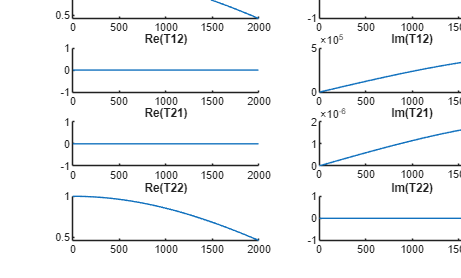

S = obj.Configuration.Section;
w = env.w;
air = env.air;
param = air.parameters;
c0 = param.c0;
k0 = w ./ c0;
Z0 = c0 * param.rho;
H = obj.Configuration.Thickness;

T.T11 = cos(k0 * H);
T.T12 = 1j * Z0 / S * sin(k0 * H);
T.T21 = 1j * S / Z0 * sin(k0 * H);
T.T22 = cos(k0 * H);

perso_plot_transfer_matrix(T,env,'exemple_cavité_air');